# E2bis

## Exercici 2

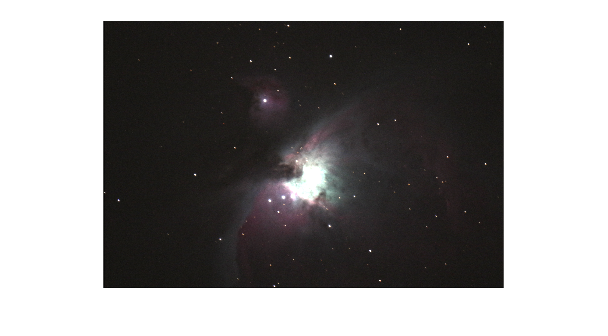

A = double(imread('_MG_7735.jpg'))/255;
B = double(imread('_MG_7737.jpg'))/255;

subplot(221);imagesc(A);axis image
[x1 y1] = ginput(1); Comenat per no reseleccionar cada cop
subplot(222);imagesc(B);axis image
[x2 y2] = ginput(1); Comenat per no reseleccionar cada cop

x = x1-x2;
y = y1-y2;

T = maketform('affine',[1 0 x;0 1 y; 0 0 1]');
Bnew = imtransform(B,T,'xdata',[1 size(A,2)],'ydata',[1 size(A,1)]);

D = A + C;
imshow(D)

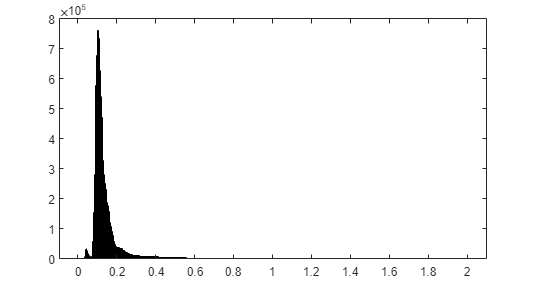

Dhsv = rgb2hsv(D);
h = Dhsv(:, :, 3);
s = Dhsv(:, :, 2);
histogram(h);

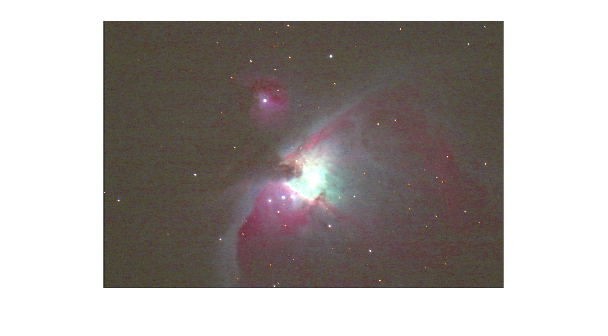


Dhsv(:, :, 3) = sqrt(h);
Dhsv(:, :, 2) = s*1.5;
Drgb = hsv2rgb(Dhsv);
imshow(Drgb)

## Sistema de vigilancia

v = VideoReader('atrium.mp4');
Background = double(rgb2gray(readFrame(v)));

while hasFrame(v)
    Actual = double(rgb2gray(readFrame(v)));
    Dif = abs(Actual - Background) > 40;
    imshow(Dif, []);
    drawnow
    Background = 0.9*Background + 0.1*Actual;
end